## FFT demo - Fourier uncertainty principle

Start by making a discrete time vector... 

clear
time = 0.001:0.001:5; % Five seconds of discrete time, sampled at 1000 Hz

now, a Brownian noise (biorealistic) time series not unlike EEG/LFP, representing one trial of neural mass data

temp1 = rand(size(time))-.5; % zero-centered white nois
brownsig = cumsum(temp1);  % Brownian noise is the cumulative sum of white nois
figure
plot(time, brownsig),title('The Brownian noise') 

Now, add 10.8 Hz sine wave to the Brownian noise

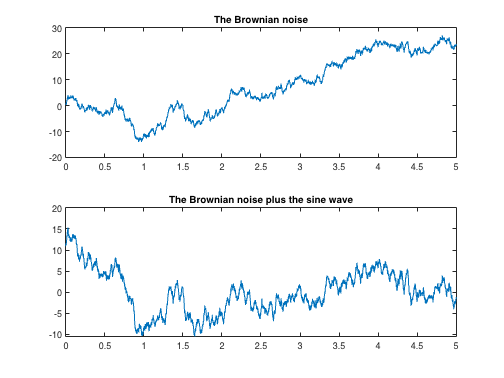

SinWave = sin(2*pi*time*10.8); % a 10.8 Hz sine wave
testsig2  = brownsig-mean(brownsig); % zero-centered Brownian noise
testsig1 = testsig2 + SinWave; % add the sine wave
testsig = regressionMAT(testsig1); % detrend
figure
subplot(2,1,1), plot(time, brownsig), title('The Brownian noise') % the real part
subplot(2,1,2), plot(time, testsig), title('The Brownian noise plus the sine wave') 

Now, the Discrete Fourier Transform, resulting in a complex spectrum with real (cosine-base) and imaginary (sine-base) components

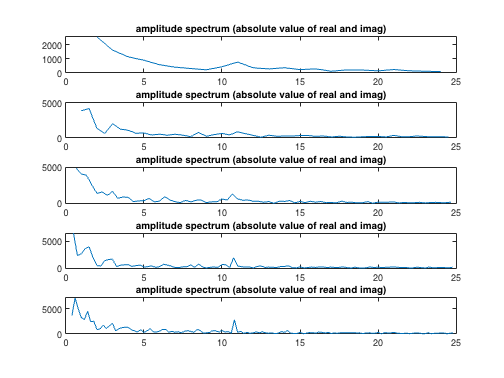

figure
for index = 1:5
    segment = 1:1000*index; % look at increasing segments
    complexspectrum = fft(testsig(segment));
    faxis = 0:1000/length(segment):500; % the frequancy axis always ranges from 0 to 500, but steps get smaller as length increases
    amplitudespec = complexspectrum./length(segment); % normalized amplitude spectrum
    subplot(5,1,index), b1 = plot(faxis(3:25*index), abs(complexspectrum(3:25*index))); title('amplitude spectrum (absolute value of real and imag)') % the absolute value (amplitude)
end